# 3.1 Interpolating Polynoms

## CP3

Verifying that my function works by checking that inputting $x_i$ gives the correct $y_i$

x=[0 2 3]';
y=[1 3 0]';
for i=1:3
    sprintf('at x=%d, %.4f should be %d', x(i), polyinterp(x,y,x(i)), y(i))
end

ans = 'at x=0, 1.0000 should be 1'

ans = 'at x=2, 3.0000 should be 3'

ans = 'at x=3, 0.0000 should be 0'

Might as well draw a graph too:

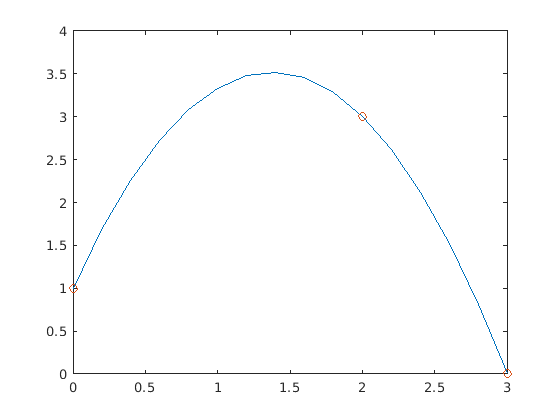

xaxis=(x(1):0.2:x(3))';
[n, ~] = size(xaxis);
for i=1:n
    yaxis(i) = polyinterp(x,y,xaxis(i));
end
hold off;

plot(xaxis, yaxis)
hold on;
plot(x,y, 'o')

function y0 = polyinterp(x,y,x0)
% POLYINTERP lalala
[n, ~] = size(x);
% Find interpolation coefficients
% using Newton's divided differences:
c = newtdd(x,y,n);
% Then evaluate the polynomial using nest:
y0 = nest(n-1,c,x0,x);
end

function c=newtdd(x,y,n)
% NEWTDD fra boka
% trekanten lagres slik i v-matrisen:
% f[x1] f[x1 x2] f[x1 x2 x3]
% f[x2] f[x2 x3]
% f[x3]
v = zeros(n,1);
for j=1:n
    v(j,1)=y(j);  % Fill in y column of Newton triangle
end
for i=2:n         % For column i,
    for j=1:n+1-i % fill in column from top to bottom
        % eksempel:
        % v(1,2) = (f[x2] - f[x1]) / (x2 - x1)
        v(j,i) = (v(j+1,i-1) - v(j,i-1)) / (x(j+i-1) - x(j));
    end
end
c = zeros(n,1);
for i=1:n
    c(i)=v(1,i); % Read along top of triangle
end              % for output coefficients
end